# Laboratorium 4

# Modulacja częstotliwości

### ***ZAD 1 MODULACJA CZĘSTOTLIWOŚCI FM***

### Opis Problemu:

Ćwiczenie polegało na:

Modulacja FM. Dobrać parametry fc, fs, Ac. Rozważamy dwa różne sygnały modulowane:

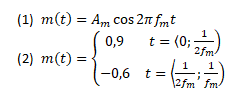

· Sprawdzić wpływ parametrów kf (czułość modulatora) oraz β (wskaźnik modulacji).

· Wykreśl widma sygnałów. Przeanalizuj wpływ parametrów.

· W każdym z przypadków wyznacz moc sygnałów modulujących, nośnych i zmodulowanego (sprawność).

· Wykonaj demodulację sygnału poprzez wyznaczenie obwiedni zespolonej (*), a następnie zróżniczkowanie widma fazowego otrzymanego sygnału.

 gdzie 𝑠̂(𝑡) to transformata Hilberta sygnału s(t) (*) Wyniki porównaj z wbudowanymi funkcjami Matlaba fmmod i fmdemod.

Modulacja FM różni się od modulacji AM, tym że sygnał modulujący zamiast wpływać na amplitudę wpływa na częstotliwość nośnej. W tym sprawozdaniu będziemy modulowac oraz demodulować sygnały, analizowac ich widma, a także badac wpływ parametrów modulacji na jej przebieg.                             

### Podstawy matematyczne:

Sygnał nośnej jest reperezentowany przez nastepujący wzór:

                 

Postać ogólna modulacji częstotliwości:

Czułość modulatora określa w jakim stopniu zmienia się częstotliwość sygnału nośnego pod wpływem modulacji. 

                                 

Wskaźnik modulacji( β) jest parametrem, który określa dewiację czestotliwości.

                                        

Demodulację można przeprowadzić poprzez wyznaczenie obwiedni zespolonej sygnału zmodulowanego:

         

#### Sygnał:

clc; clear; close all;

fs = 100000; %częstotliwość próbkowania
t = 0:1/fs:1-(1/fs);
th =  0:1/fs:1 - 2 * (1/fs);

Parametry nośnej:

Ac = 1;
fc =8000;


Parametry sygnału modulującego:

Am = 1;
fm = 10;

delta_f = fc - fm; %dewiacja częstotliwości
kf = delta_f / Am  %czułość modulatora

kf = 7990

B = (kf * Am) / fm  %wskaźnik modulacji

B = 799

%sygnał modulujący
signal = Am*cos(2*pi*fm*t);

%sygnał zmodulowany
Sfm = Ac*cos(2*pi*fc*t + B*sin(2*pi*fm*t));

%dft
dft_signal = fft(signal);
dft_Sfm = fft(Sfm);

freq=(-length(t)/2:(length(t)/2 - 1));

%moce sygnałów
moc_sygnalu_modulujacego = rms(signal)^2

moc_sygnalu_modulujacego = 0.5000

moc_sygnalu_zmodulowanego = rms(Sfm)^2

moc_sygnalu_zmodulowanego = 0.5162

sprawnosc = (moc_sygnalu_modulujacego / moc_sygnalu_zmodulowanego) * 100

sprawnosc = 96.8709

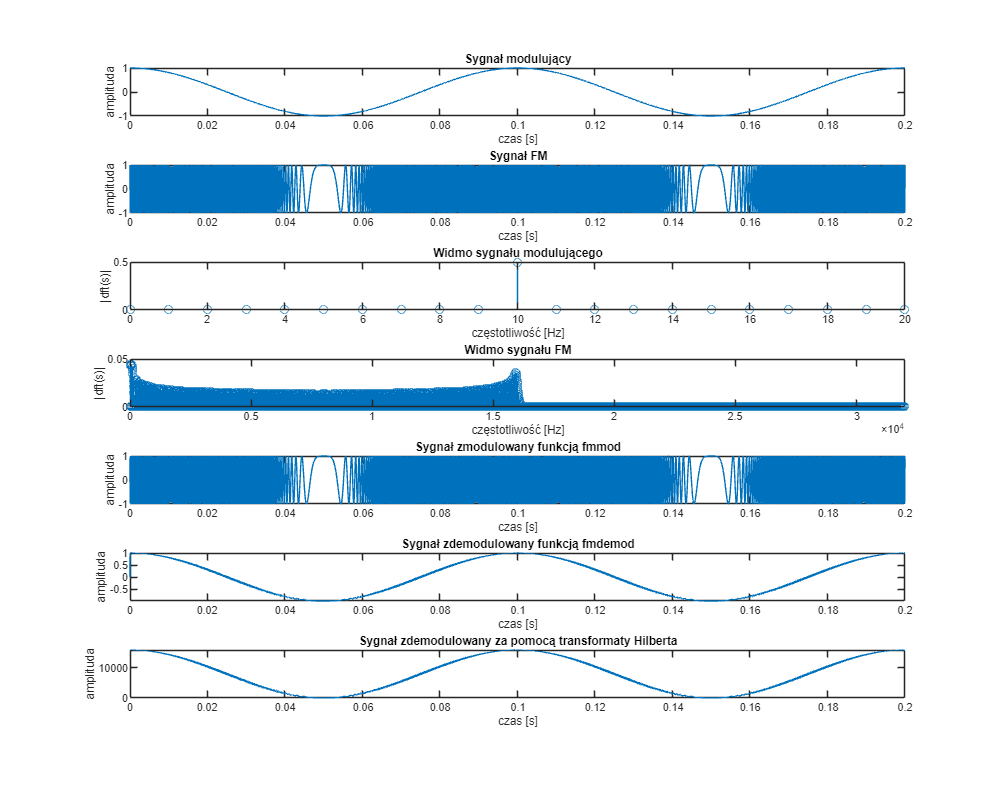

%modulacje demodulacje
modulated_signal = fmmod(signal, fc, fs, delta_f);

demodulated_signal = fmdemod(modulated_signal, fc, fs, delta_f);
w = unwrap(angle(hilbert(Sfm)));
hilbert_demodulated_signal = ((diff(w)/(2*pi*1/fs)));

%wykresy
fig1 = figure;
fig1.Position = [0, 0, 1000, 800];

subplot(7,1,1)
plot(t, signal)
xlim([0, 2/fm])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał modulujący')

subplot(7,1,2)
plot(t, Sfm)
xlim([0, 2/fm])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał FM')

subplot(7,1,3)
stem(freq, abs(fftshift(dft_signal))/length(t))
xlim([0, fm * 2])
xlabel('częstotliwość [Hz]')
ylabel('|dft(s)|')
title('Widmo sygnału modulującego')

subplot(7,1,4)
stem(freq, abs(fftshift(dft_Sfm))/length(t))
xlim([0, fc * 4])
xlabel('częstotliwość [Hz]')
ylabel('|dft(s)|')
title('Widmo sygnału FM')

subplot(7,1,5)
plot(t, modulated_signal)
xlim([0, 2/fm])
xlabel('czas [s]')
ylabel('amplituda')
title('Sygnał zmodulowany funkcją fmmod')

subplot(7,1,6)
plot(t, demodulated_signal)
xlim([0, 2/fm])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał zdemodulowany funkcją fmdemod')

subplot(7,1,7)
plot(th, hilbert_demodulated_signal)
xlim([0, 2/fm])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał zdemodulowany za pomocą transformaty Hilberta')

#### Sygnał:

clc; clear; close all;

fs = 100000; %częstotliwość próbkowania
t = 0:1/fs:1-(1/fs);
th =  0:1/fs:1 - 2 * (1/fs);


Parametry nośnej:

Ac = 2;
fc =9200;

Parametry sygnału modulującego:

Am = 1;
fm = 100;

delta_f = fc - fm; %dewiacja częstotliwości
kf = delta_f / Am  %czułość modulatora

kf = 9100

B = (kf * Am) / fm  %wskaźnik modulacji

B = 91

%sygnał modulujący
signal = Am * square(2*pi*fm*t) * 0.75 + 0.15;

%sygnał zmodulowany
%Sfm = Ac*cos(2*pi*fc*t + B * (square(2*pi*fm*t) * 0.75 + 0.15));
Sfm = Ac * fmmod(signal, fc, fs, delta_f);

%dft
dft_signal = fft(signal);
dft_Sfm = fft(Sfm);

freq=(-length(t)/2:(length(t)/2 - 1));

%moce sygnałów
moc_sygnalu_modulujacego = rms(signal)^2

moc_sygnalu_modulujacego = 0.5850

moc_sygnalu_zmodulowanego = rms(Sfm)^2

moc_sygnalu_zmodulowanego = 2.0002

sprawnosc = (moc_sygnalu_modulujacego / moc_sygnalu_zmodulowanego) * 100

sprawnosc = 29.2497

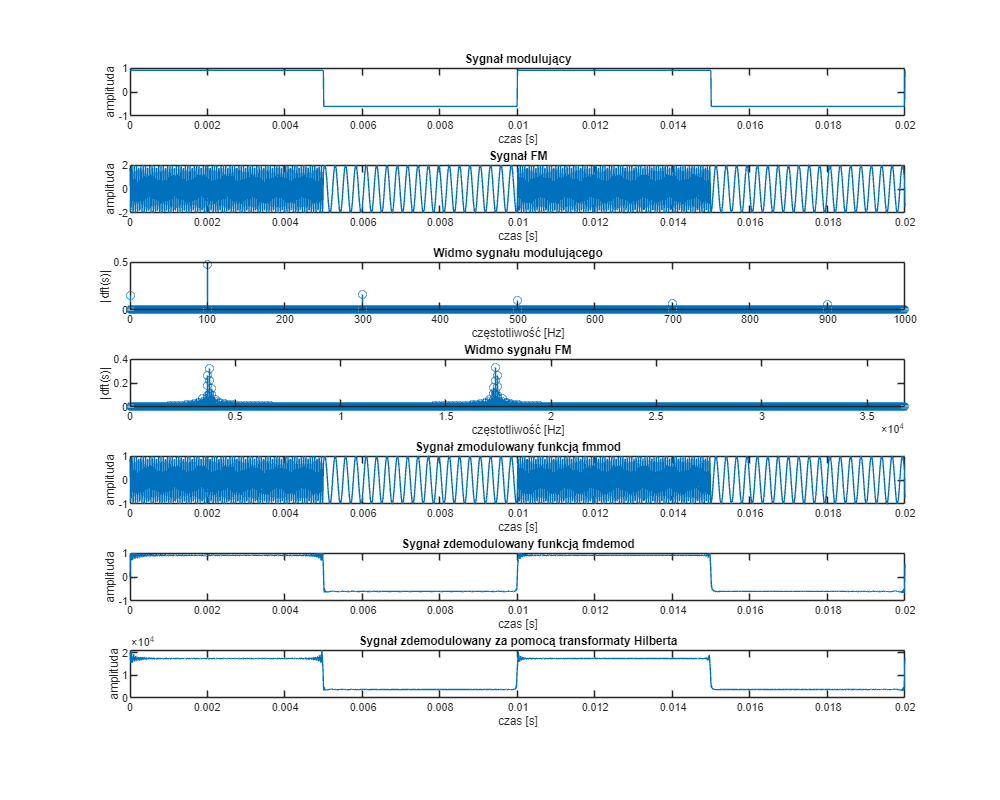

%modulacje demodulacje
modulated_signal = fmmod(signal, fc, fs, delta_f);

demodulated_signal = fmdemod(modulated_signal, fc, fs, delta_f);
w = unwrap(angle(hilbert(Sfm)));
hilbert_demodulated_signal = ((diff(w)/(2*pi*1/fs)));

%wykresy
fig2 = figure;
fig2.Position = [0, 0, 1000, 800];

subplot(7,1,1)
plot(t, signal)
xlim([0, 2/fm])
ylim([-Am, Am])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał modulujący')

subplot(7,1,2)
plot(t, Sfm)
xlim([0, 2/fm])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał FM')

subplot(7,1,3)
stem(freq, abs(fftshift(dft_signal))/length(t))
xlim([0, fm * 10])
xlabel('częstotliwość [Hz]')
ylabel('|dft(s)|')
title('Widmo sygnału modulującego')

subplot(7,1,4)
stem(freq, abs(fftshift(dft_Sfm))/length(t))
xlim([0, fc * 4])
xlabel('częstotliwość [Hz]')
ylabel('|dft(s)|')
title('Widmo sygnału FM')

subplot(7,1,5)
plot(t, modulated_signal)
xlim([0, 2/fm])
xlabel('czas [s]')
ylabel('amplituda')
title('Sygnał zmodulowany funkcją fmmod')

subplot(7,1,6)
plot(t, demodulated_signal)
xlim([0, 2/fm])
ylim([-Am, Am])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał zdemodulowany funkcją fmdemod')

subplot(7,1,7)
plot(th, hilbert_demodulated_signal)
xlim([0, 2/fm])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał zdemodulowany za pomocą transformaty Hilberta')

### Obserwacje i wnioski:

- Parametr β określa odchył od częstotliwości nośnej przy danym sygnale modulującym. Z analizy wynika, że im większa wartość β, tym większe pasmo zajmuje widmo sygnału zmodulowanego. 

- Ważne jest aby częstotliwość sygnału zmodulowanego była zależna liniowo od amplitudy sygnału modulującego.

- Widmo kosinusa zawiera tylko jeden prążek, a przebiegu prostokątnego kilka prążków harmonicznych, co jest zgodne z oczekiwaniami.

- Widmo sygnału zmodulowanego zawiera dwie wstęgi boczne, świadczy to o poprawności modulacji.

- Wraz ze wzrostem amplitudy sygnału modulującego wzrasta czestotliwośc sygnału zmodulowanego.

- Gdy amplitudy sygnałów są podobne, sprawność modulacji jest bardzo wysoka w porównaniu do modulacji AM.

- Gdy wskaźnik modulacji ma zbyt dużą wartosć, sygnał po demodulacji nie oddaje już wiernie sygnału modulującego (zniekształceniu ulega amplituda, a w widmie pojawiają się dodatkowe prażki częstotliwości).

- Gdy wskaźnik modulacji jest bardzo mały, kozystamy z modulacji wąskopasmowej.

- Dla typowych wartości wskaźnika modulacji, transformata Hilberta dobrze odwzorowuje obwiednię sygnału(lecz zwraca dziwną amplitudę).

### ***ZAD 2 MODULACJA WĄSKOPASMOWA FM***

### Opis Problemu:

Ćwiczenie polegało na:

. Wąskopasmowa modulacja FM. Dobrać parametry fc, fs, Ac.

· Sprawdzić wpływ parametrów kf (czułość modulatora), β wskaźnik modulacji oraz relacje Am/ /Ac

· Wykreśl sygnały i ich widma. Przeanalizuj wpływ parametrów.

· Wykonaj demodulację sygnału.

Celem ćwiczenia jest zbadanie wąskopasmowej modulacji FM.

### Podstawy matematyczne:

Wzór na postać sygnału zmoduowanego wąskopasmowo możemy zapisac w następujący sposób:

                 

clc; clear; close all;

fs = 100000; %częstotliwość próbkowania
t = 0:1/fs:1-(1/fs);
th =  0:1/fs:1 - 2 * (1/fs);


Parametry nośnej:

Ac = 1;
fc =1000;


Parametry sygnału modulującego:

Am = 1;
fm = 300;

delta_f = fc - fm; %dewiacja częstotliwości
kf = delta_f / Am  %czułość modulatora

kf = 700

B = 0.2;  %wskaźnik modulacji

stosunek_amplitudy_sygnalu_modulujacego_do_amplitudy_nosnej = Am/Ac

stosunek_amplitudy_sygnalu_modulujacego_do_amplitudy_nosnej = 1

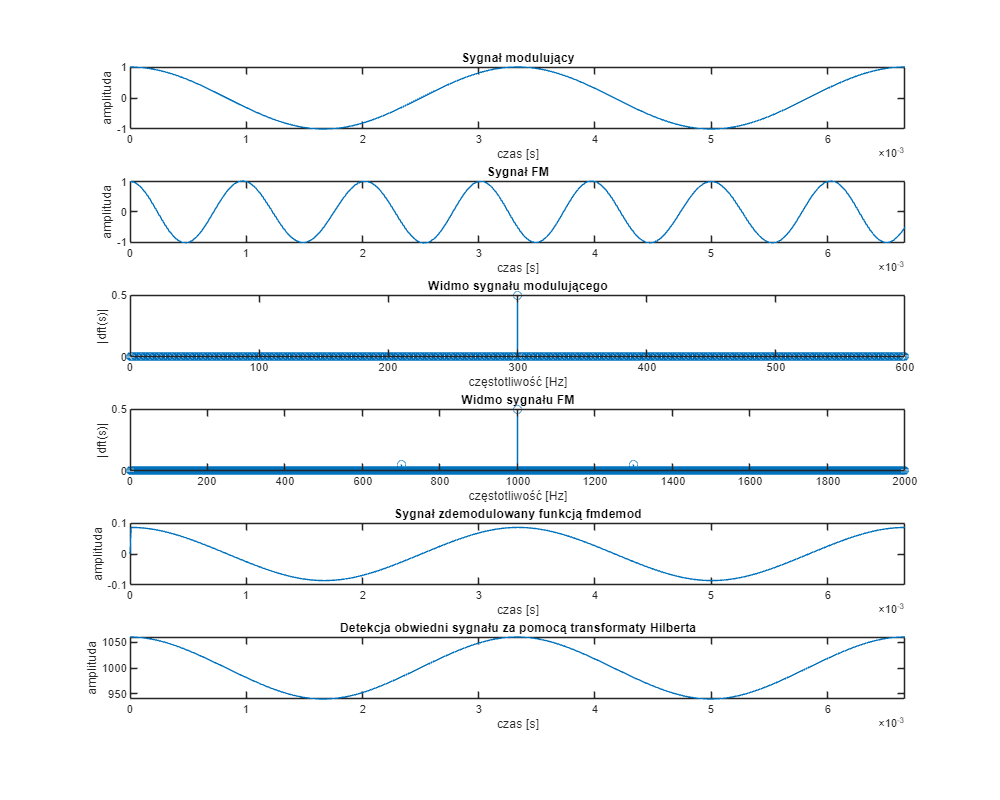


%sygnał modulujący
signal = Am*cos(2*pi*fm*t);

%sygnał zmodulowany
Sfm = Ac*(cos(2*pi*fc*t) - sin(2*pi*fc*t)*B.*sin(2*pi*fm*t));

%dft
dft_signal = fft(signal);
dft_Sfm = fft(Sfm);

freq=(-length(t)/2:(length(t)/2 - 1));

%modulacje demodulacje
demodulated_signal = fmdemod(Sfm, fc, fs, delta_f);

w = unwrap(angle(hilbert(Sfm)));
demodulated_signal_am = ((diff(w)/(2*pi*1/fs)));

%wykresy
fig3 = figure;
fig3.Position = [0, 0, 1000, 800];

subplot(6,1,1)
plot(t, signal)
xlim([0, 2/fm])
ylim([-Am, Am])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał modulujący')

subplot(6,1,2)
plot(t, Sfm)
xlim([0, 2/fm])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał FM')

subplot(6,1,3)
stem(freq, abs(fftshift(dft_signal))/length(t))
xlim([0, fm * 2])
xlabel('częstotliwość [Hz]')
ylabel('|dft(s)|')
title('Widmo sygnału modulującego')

subplot(6,1,4)
stem(freq, abs(fftshift(dft_Sfm))/length(t))
xlim([0, fc * 2])
xlabel('częstotliwość [Hz]')
ylabel('|dft(s)|')
title('Widmo sygnału FM')

subplot(6,1,5)
plot(t, demodulated_signal)
xlim([0, 2/fm])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał zdemodulowany funkcją fmdemod')

subplot(6,1,6)
plot(th, demodulated_signal_am)
xlim([0, 2/fm])
xlabel("czas [s]")
ylabel("amplituda")
title('Detekcja obwiedni sygnału za pomocą transformaty Hilberta')

### Obserwacje i wnioski:

- Gdy β = 1 ten typ modulacji zachowuję się podobnie do modulacji AM.

- Dla modulacji wąskopasmowej β < 1.

- Gdy  β jest mała demodulacja za pomocą funkcji fmdemod i transformaty Hilberta, stosunkowo dobrze odwzorowuje sygnał modulujący.

- Widmo sygnału zmodulowanego wygląda bardzo podobnie do widma modulacji AM.

- Wadą tego typu modulacji jest potrzeba zwiększania amplitudy nośnej, co powoduje wzrost pobieranej mocy.

- Dużą zaleta jest bardzo małe pasmo transmisji.

### ***ZAD 3 MODULACJA SZEROKOPASMOWA FM***

3. Szerokopasmowa modulacja FM. Wykonaj modulację jednotonową w oparciu o funkcje Bessela pierwszego rodzaju. Porównaj kryterium jednoprocentowe (amplituda składowych przekracza 1% amplitudy sygnału niezmodulowanego) i regułę Carsona w zależności od parametrów sygnałów składowych, czułości modulacji, β (wskaźnik modulacji) pod względem wpływu na pasmo sygnału FM.

### Podstawy matematyczne:

Z modulacją szerokopasmową FM mamy doczynienia gdy współczynnik modulacji  β > 1. Dla modulacji jednotonowej sygnał zmodulowany określany jest wzorem:

Możemy go też określić z pomocą funkcji Bessela pierwszego rzędu. Wtedy wzór przyjmie postać:

Gdzie:

$J_k \left(\beta \right)$ - jest funkcją Bessela k-tego rzędu. Implementujemy ją za pomocą funkcji matlaba besselj

$f_c$ - częstotliwość fali nośnej

$f_m$ - częstotliwość sygnału modulującego

$t$ - wektor czasu

#### Kryterium Jednoprocentowe:

Kryterium mówiące, że jedynie składowe sygnału których amplitudy przekraczają 1% amplitudy nośnej zawierają istotne informacje. Pozostałe składowe mogą zostać pominięte bez znacznej utraty jakości sygnału.

#### Reguła Carsona:

Widmo sygnału modulowanego FM jest nieskończenie rozległe, zajmuje nieskończenie duże pasmo. Jednakże amplitudy wstęg bocznych szybko maleją do zera. Zgodnie z regułą Carsona wyrażoną zależnością , w paśmie 2ΔF mieszczą się wstęgi, których obecność zapewnia wysoką wierność transmisji.

Reguła Carsona pozwala ograniczyć pasmo transmisji sygnału o modulowanej częstotliwości bez szkody dla jakości transmisji.

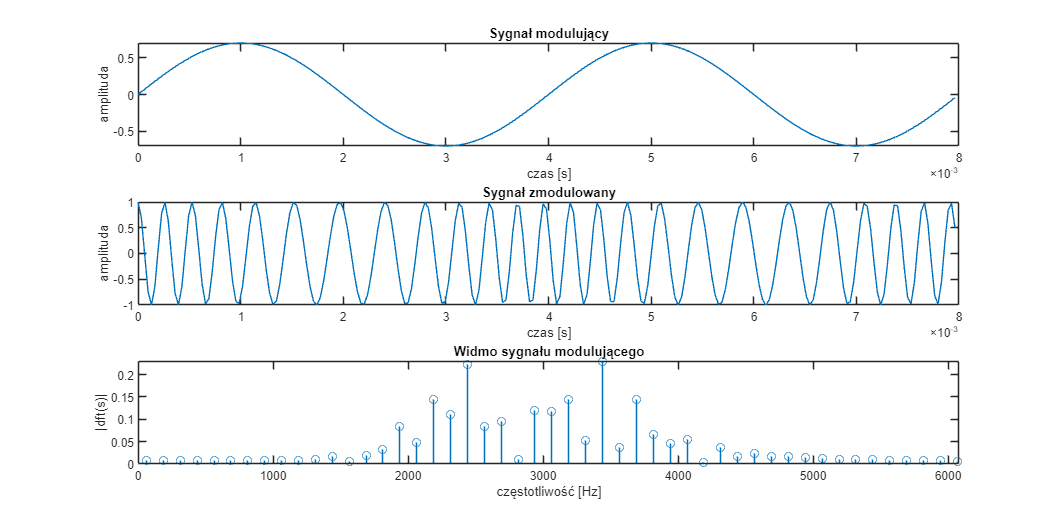

clc; clear; close all;

fc = 3040;
Ac = 1;
fm = 250;
Am = 0.7;
Beta = 3;

dt = 1/(fc*10);
t = 0:dt:(2/fm)-dt;
freq=(-length(t)/2:(length(t)/2 - dt));
freq = (freq/length(freq) * (1/dt));

signal = Am * sin(2*pi*fm*t);

% Sfm = zeros(1, length(t));
% 
% for k = -20:20
%     Sfm = Sfm + (besseli(k, Beta).*cos(2*pi*(fc+(k*fm)).*t));
% end
% 
% Sfm = Ac * Sfm;

%s_fm = cos(2*pi*fc*t + Kf * besselj(0, beta) * cumsum(m)/fs);

J1 = besseli(0, Beta);
Sfm = Ac * cos(2*pi*fc*t + Am * J1 * sin(2*pi*fm*t));


dft_Sfm = fft(Sfm);

%wykresy
fig3 = figure;
fig3.Position = [0, 0, 2000, 1000];

subplot(3,1,1)
plot(t, signal)
ylim([-Am, Am])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał modulujący')

subplot(3,1,2)
plot(t, Sfm)
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał zmodulowany')

subplot(3,1,3)
stem(freq, abs(fftshift(dft_Sfm))/length(t))
xlabel('częstotliwość [Hz]')
xlim([0, 2*fc])

ylabel('|dft(s)|')
title('Widmo sygnału modulującego')

## Obserwacje:

Wraz ze wzrostem Bety obserwujemy poszerzanie się wstęg bocznych tzn poszerzanie się pasma transmisji.

Pasmo jest większe niż w przypadku modulacji wąskopasmowej natomiast zdemodulowany sygnał będzie przez to lepszej jakości.

## Wnioski:

Aby zdecydowac pominiecie których prążków wstęg bocznych nie spowoduje znacznego pogorszenia jakości sygnału możemy zastosować Kryterium jednoprocentowe lub regułę Carsona. Jako że obliczenie które prążki są mniejsze niż poziom 1% amplitudy nośnej jest dosyć kosztowne obliczeniowo w praktyce stosuje się regułę Carsona i zakłada pasmo sygnału jako $2\Delta f+2f_s$.